# Example 1:

### F: Quadratic function | C: Rn+ | tk = 0.1

x0 = [-0.9; 1];
projection_Rnp(x0)

ans =      0
     1


tolerance = 1e-6;
x0 = [1; 0.1];
x = gradient_projection_method(tolerance, x0, @projection_Rnp, ...
    @(x) 0.1, @gradient_quadratic, @quadratic);

iter_number = 0 func = 1.0200000 x = [1,0.1]  
iter_number = 1 func = 0.6472000 x = [0.8,0.06]  
iter_number = 2 func = 0.4121920 x = [0.64,0.036]  
iter_number = 3 func = 0.2630771 x = [0.512,0.0216]  
iter_number = 4 func = 0.1681081 x = [0.4096,0.01296]  
iter_number = 5 func = 0.1074951 x = [0.32768,0.007776]  
iter_number = 6 func = 0.0687630 x = [0.26214,0.0046656]  
iter_number = 7 func = 0.0439961 x = [0.20972,0.0027994]  
iter_number = 8 func = 0.0281531 x = [0.16777,0.0016796]  
iter_number = 9 func = 0.0180164 x = [0.13422,0.0010078]  
iter_number = 10 func = 0.0115299 x = [0.10737,0.00060466]  
iter_number = 11 func = 0.0073790 x = [0.085899,0.0003628]  
iter_number = 12 func = 0.0047225 x = [0.068719,0.00021768]  
iter_number = 13 func = 0.0030223 x = [0.054976,0.00013061]  
iter_number = 14 func = 0.0019343 x = [0.04398,7.8364e-05]  
iter_number = 15 func = 0.0012379 x = [0.035184,4.7018e-05]  
iter_number = 16 func = 0.0007923 x = [0.028147,2.8211e-05]  
iter_number = 17

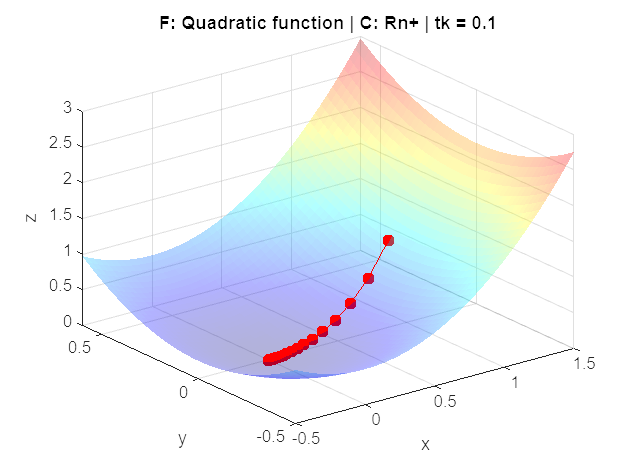

title('F: Quadratic function | C: Rn+ | tk = 0.1')

# Example 2:

### F: Quadratic function | C: Box[[1;1], [2;3]] | tk = 0.02

x0 = [0.9; 3.1];
projection_Box(x0, [1;1], [2;3])

ans =      1
     3


tolerance = 1e-6;
x0 = [1.5; 2.1];
x = gradient_projection_method(tolerance, x0, ... 
    @(x) projection_Box(x, [1;1], [2;3]), ...
    @(x) 0.02, @gradient_quadratic, @quadratic);

iter_number = 0 func = 11.0700000 x = [1.5,2.1]  
iter_number = 1 func = 9.5388480 x = [1.44,1.932]  
iter_number = 2 func = 8.2296157 x = [1.3824,1.7774]  
iter_number = 3 func = 7.1092561 x = [1.3271,1.6352]  
iter_number = 4 func = 6.1497170 x = [1.274,1.5044]  
iter_number = 5 func = 5.3271796 x = [1.2231,1.3841]  
iter_number = 6 func = 4.6214145 x = [1.1741,1.2733]  
iter_number = 7 func = 4.0152357 x = [1.1272,1.1715]  
iter_number = 8 func = 3.4940382 x = [1.0821,1.0778]  
iter_number = 9 func = 3.0791075 x = [1.0388,1]  
iter_number = 10 func = 3.0000000 x = [1,1]  
iter_number = 11 func = 3.0000000 x = [1,1]  


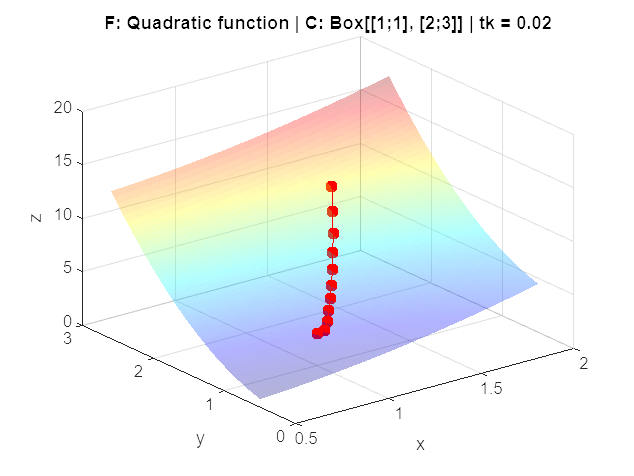

title('F: Quadratic function | C: Box[[1;1], [2;3]] | tk = 0.02')

# Example 3:

### F: Quadratic function | C: Ball[[3;3],2] | tk = 0.1

x0 = [1; 0];
projection_Ball(x0, [3; 3], 2)

ans =     1.8906
    1.3359


tolerance = 1e-6;
x0 = [3.1; 2.1];
center = [3; 3];
x = gradient_projection_method(tolerance, x0, ... 
    @(x) projection_Ball(x, center, 2), ...
    @(x) 0.1, @gradient_quadratic, @quadratic);9

iter_number = 0 func = 18.4300000 x = [3.1,2.1]  
iter_number = 1 func = 9.3256000 x = [2.48,1.26]  
iter_number = 2 func = 7.5065845 x = [2.1751,1.178]  
iter_number = 3 func = 7.2598366 x = [2.0369,1.2471]  
iter_number = 4 func = 7.1785587 x = [1.9602,1.2916]  
iter_number = 5 func = 7.1526062 x = [1.9177,1.3181]  
iter_number = 6 func = 7.1444668 x = [1.8942,1.3335]  
iter_number = 7 func = 7.1419399 x = [1.8812,1.3422]  
iter_number = 8 func = 7.1411599 x = [1.874,1.3471]  
iter_number = 9 func = 7.1409198 x = [1.87,1.3498]  
iter_number = 10 func = 7.1408461 x = [1.8678,1.3513]  
iter_number = 11 func = 7.1408235 x = [1.8666,1.3521]  
iter_number = 12 func = 7.1408165 x = [1.8659,1.3526]  
iter_number = 13 func = 7.1408144 x = [1.8656,1.3529]  
iter_number = 14 func = 7.1408137 x = [1.8654,1.353]  
iter_number = 15 func = 7.1408135 x = [1.8652,1.3531]  
iter_number = 16 func = 7.1408135 x = [1.8652,1.3531]  
iter_number = 17 func = 7.1408135 x = [1.8651,1.3532]  
iter_number = 18

ans = 9

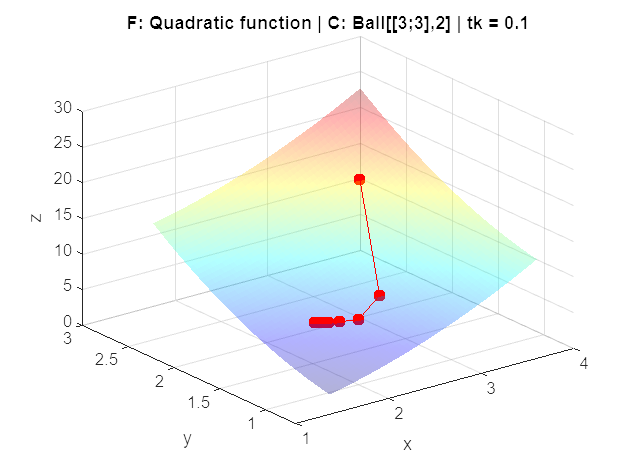

title('F: Quadratic function | C: Ball[[3;3],2] | tk = 0.1')